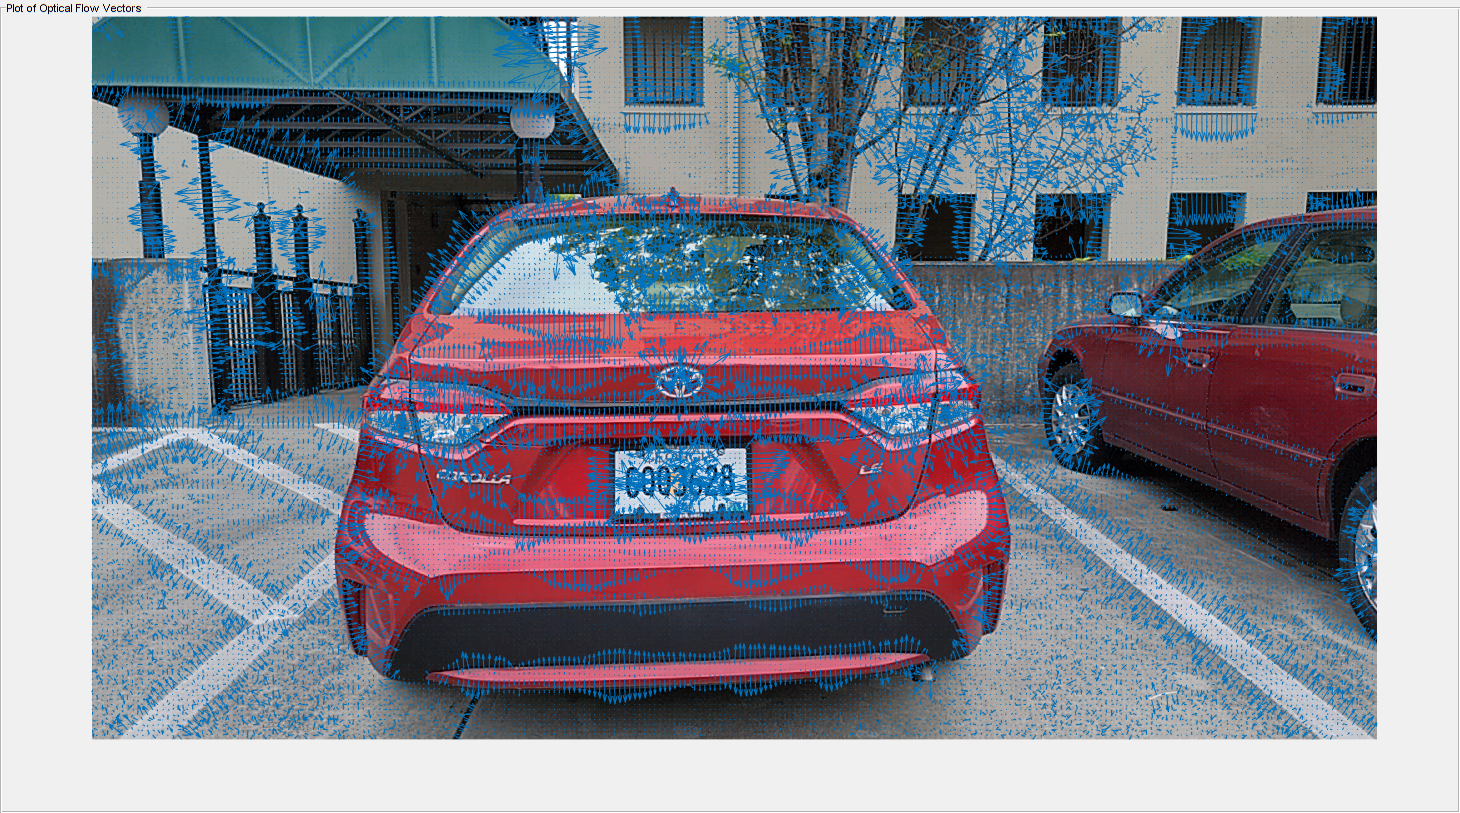

vidReader = VideoReader('video.mp4');
opticFlow = opticalFlowHS;
h = figure;
movegui(h);
hViewPanel = uipanel(h,'Position',[0 0 1 1],'Title','Plot of Optical Flow Vectors');
hPlot = axes(hViewPanel);
c=0;
n=1;
while hasFrame(vidReader)
        frameRGB = readFrame(vidReader);
        frameGray = im2gray(frameRGB); 
    if mod(c,n)==0 
        flow = estimateFlow(opticFlow,frameGray);
        imshow(frameRGB)
        hold on
        plot(flow,'DecimationFactor',[5 5],'ScaleFactor',60,'Parent',hPlot);
        hold off
        pause(10^-3)
    else
        imshow(frameRGB)
    end


    c=c+1;
end